Made by Polyakov Anton, the part of R3236, suir family

Преподаватель: Алексей Алексеевич Перегудин

## Код Хэмминга (7, 4)

Код Хэмминга - это метод для обнаружения и исправления ошибок в передаче данных. Он добавляет дополнительные проверочные биты к данным, чтобы их можно было проверить на наличие ошибок. 

*(7,4) - значит блок длиной 7 бит и сообщение длиной 4 бита, 3 бита на кодировку всех возможных  ошибок*

Значение каждого проверочного бита рассчитывается на основе позиции в блоке. Исходные данные и значения проверочных битов формируют код Хэмминга, который передается по каналу связи.

При получении данных, получатель вычисляет значения проверочных битов и сравнивает их с принятыми данными. Если значения не совпадают, то произошла ошибка. По значениям проверочных битов можно определить ошибочный бит и восстановить исходное сообщение. **Это перестает работать при двойных и более ошибках...**

**Как это работает?**

Добавляя дополнительных 3 бита(8 состояний) мы в них закладываем восемь примерно таких состояний...

- Отсутствуют ошибки?

- Есть ли ошибка в бите 1?

- Есть ли ошибка в бите 2?  

- ...

- Есть ли ошибка в бите 7?

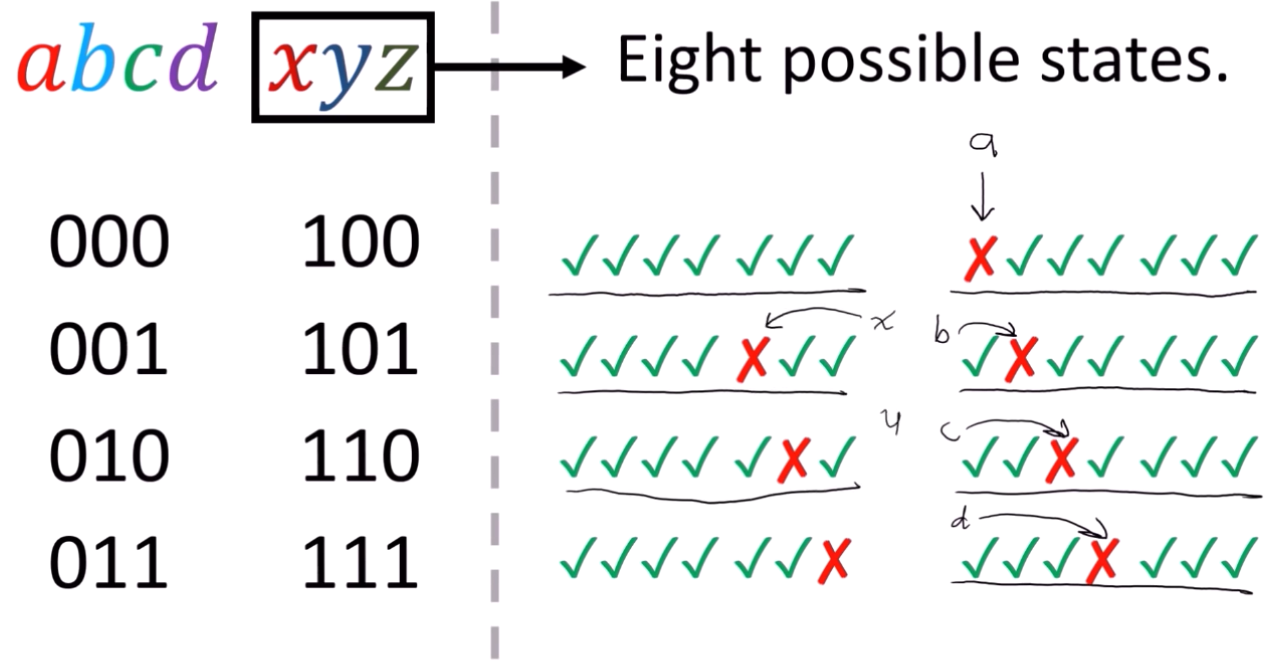

#### Почему линейный?

Потому что операции в численном варианте - это XOR, и их можно преобразовать в матричные операции

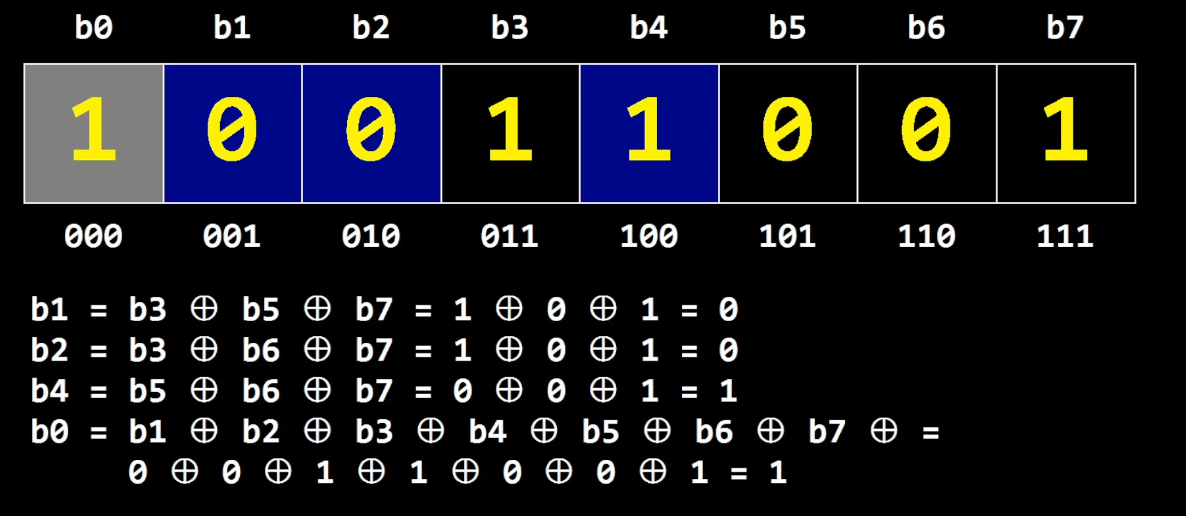

#### Про выбор порядка битов в коде

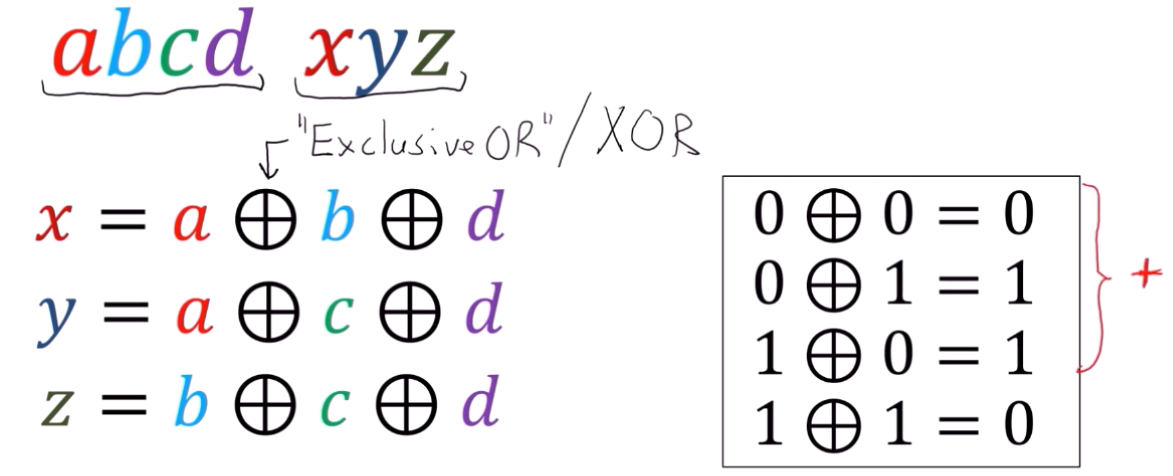

Пусть, что a,b,c,d - биты информации, x,y,z - биты проверки состояний. **Тогда [abcdxyz] - код Хэмминга в общем виде.**

При смене порядка битов местами **сменятся лишь формулы** для битов состояний, операции XOR не сменятся на другие ([свойства операции XOR](https://en.wikipedia.org/wiki/Exclusive_or))...

Начнем с того, что все проверочные состояния выбираются произвольно нами, допустим 100 будет отвечать за ошибку в третьем бите кода Хэмминга и.т.д, продолжим устанавливать соответствия

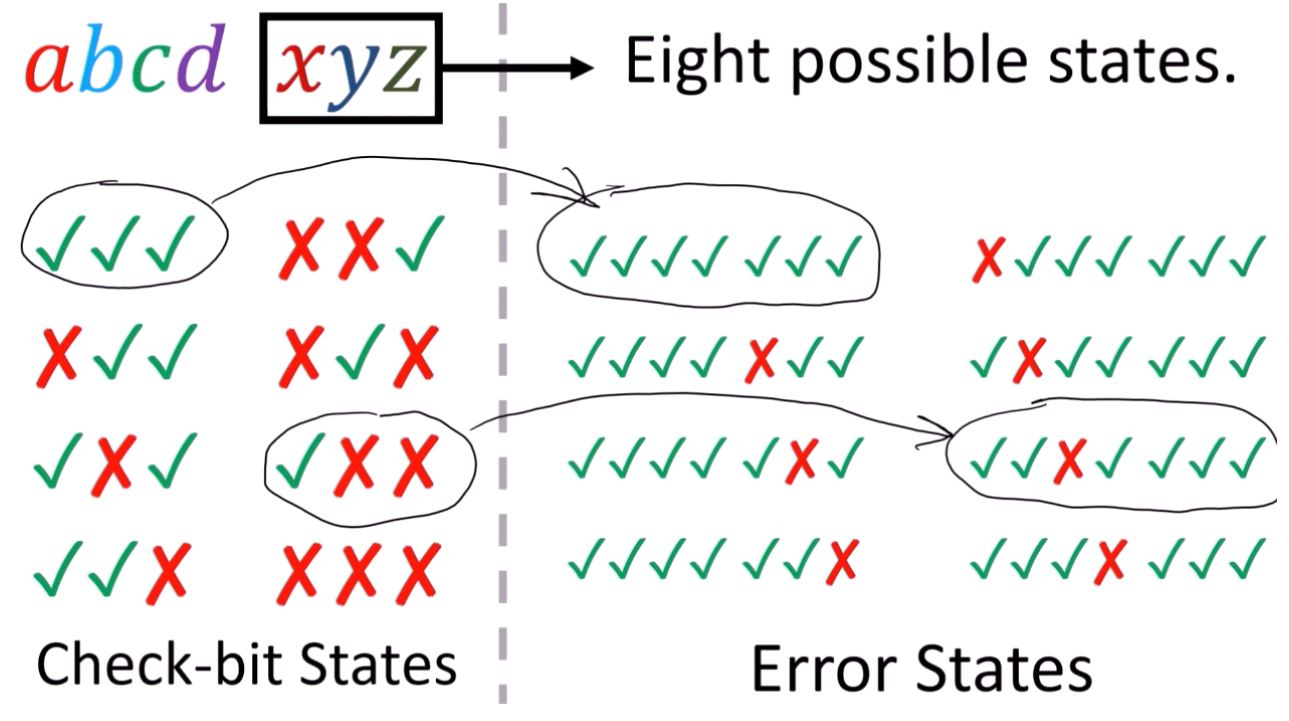

На картинке выше мы сделали биекцию между всеми возможными комбинациями битов состояний и допустимыми одиночными ошибками где-то в коде. 

Давайте рассмотрим ошибки в битах ценной информации. Как мы можем отразить в комбинации, что ошибочен какой-то ценный бит? Вариант выбора не единственнен, глянем картинку с примером.

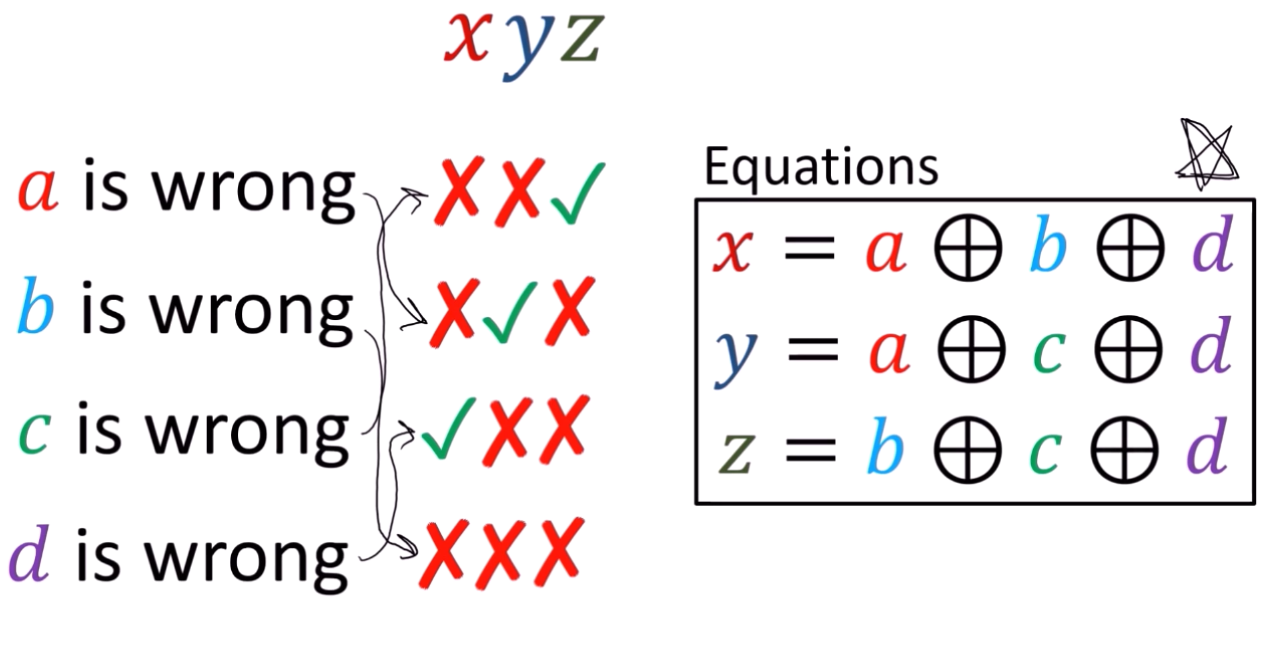

Но такие стрелочки мы можем расставить как захотим, и тогда, если посмотреть по столбцам, уравнения битов состояний просто сменит свой вид, а это правило мы лишь запишем себе на листок, чтобы потом кодировать и проверять правильно.

*В итоге допустим будет даже такой вариант кода - [axbyczd] - и конечно это повлияет на вид матриц G, H*

#### Как можно составить матрицу G?

По сути "code generator matrix" или "образующая матрица G" это линейное преобразование: 4D --> 7D пространство, которое изобразить довольно трудно. Матрица этого преобразования позволяет нам из наших данных получить код Хэмминга

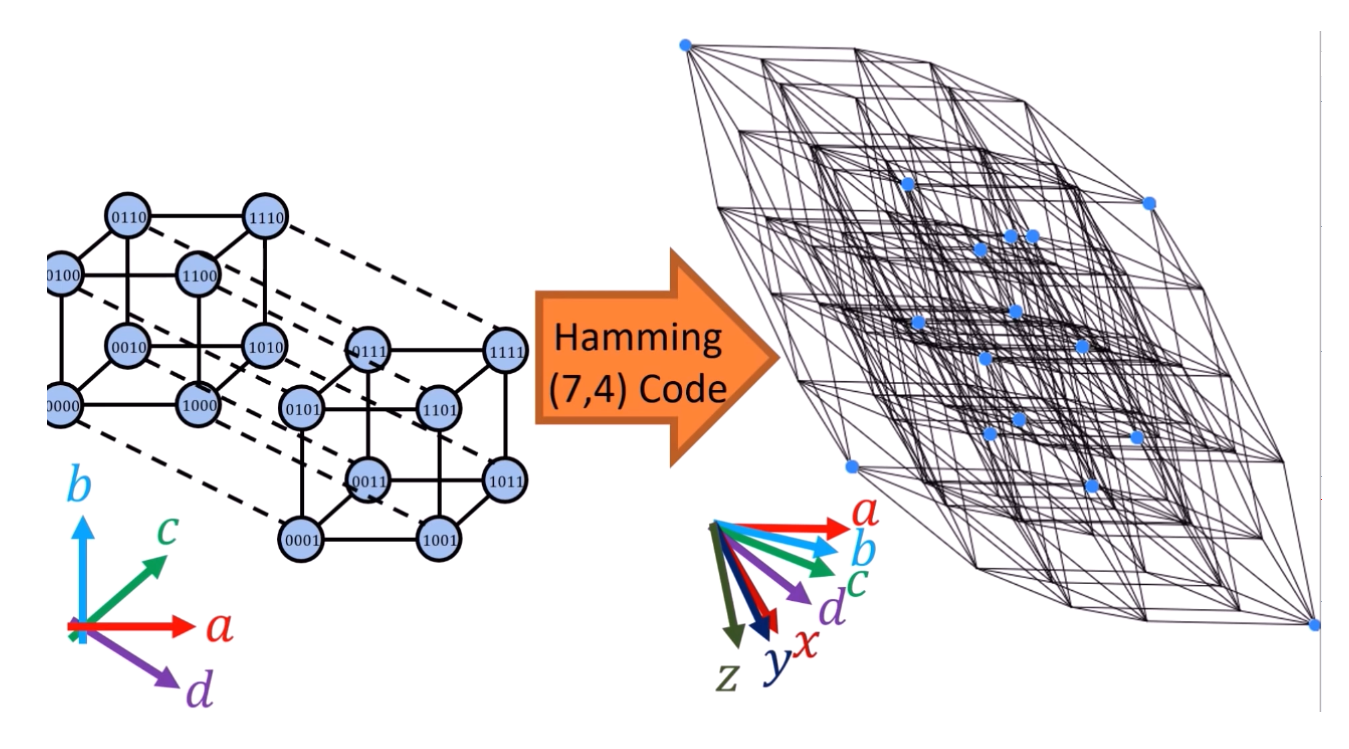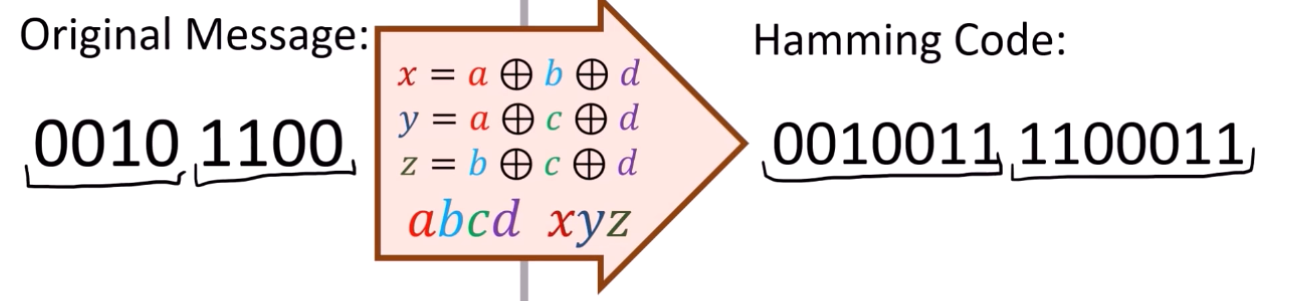

Поэтому обычно для кода Хэмминга используют численные методы или матричное представление. Рассмотрим второй вариант, так как мы в матлабе сейчас :)

На картинке ниже мы видим пример матрицы G на основе формул битов состояний, которые появились из-за выбора биекций

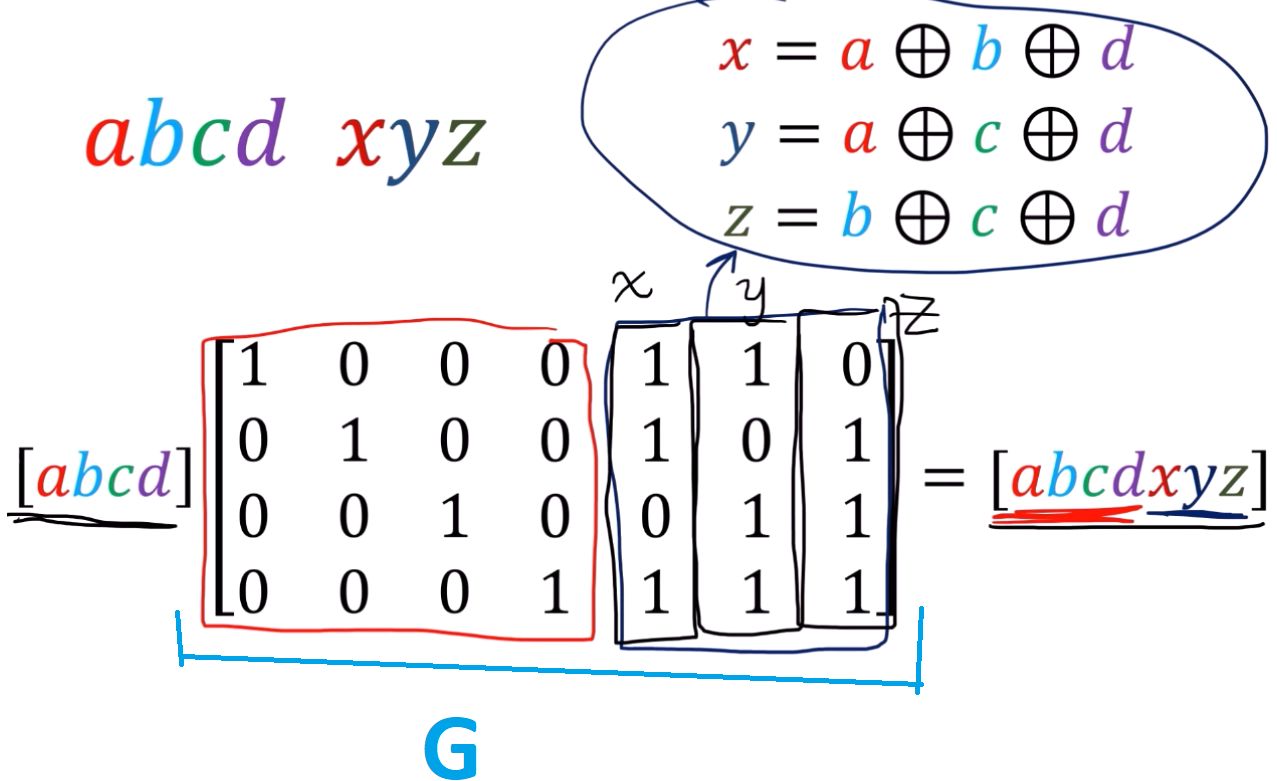

В этом случае происходит не простое матричное умножение, а еще и "взятие по модулю 2" или же XOR - кому как удобно.

Так как в итоговом коде первые 4 позиции занимает ценная информация, тогда первые 4 строки занимает матрица эквивалентного преобразования (= единичная матрица). Потом участие принимают формулы состояния, которые занимают три оставшихся места. 

Если мы захотим поменять в коде Хэмминга биты местами, нам следует поменять соответствующие им векторы-столбцы местами тоже

В моем случае я взял [*канонический базис*](https://ru.frwiki.wiki/wiki/Code_de_Hamming_(7,4)) и сразу транспонировал матрицу для удобства перемножения

G = [1 1 0 1;
     1 0 1 1;
     1 0 0 0;
     0 1 1 1;
     0 1 0 0;
     0 0 1 0;
     0 0 0 1];

#### Как можно составить матрицу H?

"parity-check matrix" или "матрица управления H" нам понадобится уже в случае ошибок, ибо из кода Хэмминга без ошибок легко считать исходные данные. 

Чтобы подружиться с примером ниже давайте на веру примем, что какая-то матрица H существует для любого G. Вспомним, что  H*C = 0, где C - код Хэмминга без ошибок. Тогда добавим в С ошибку, повторим то же самое, но по свойству линейности разобьем новый код с ошибкой на две компоненты = два вектора. Тогда один по свойству выше станет нулевым, **а второй станет проекцией столбца с матрицы H (вектор-синдром)**.

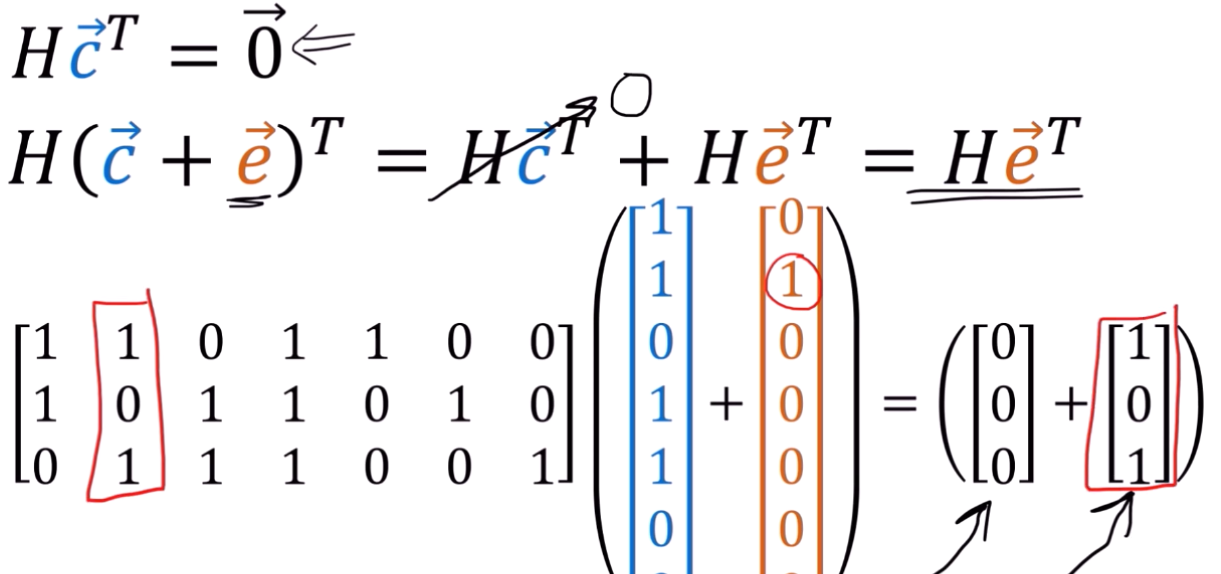

Нас это наводит на мысль, что столбцы матрицы H должны явно нам подсказывать в каком месте у вектора ошибки была единичка, т.е. какой бит ошибочный...

Кстати, если ошибок будет несколько,естественно они сложатся в единую, тогда подсказку мы не сможем получить **однозначно**

**Так как нам выбрать подсказки?**

Вспомним биекции, которые мы задали на этапе проектировки матрицы G, например такие:

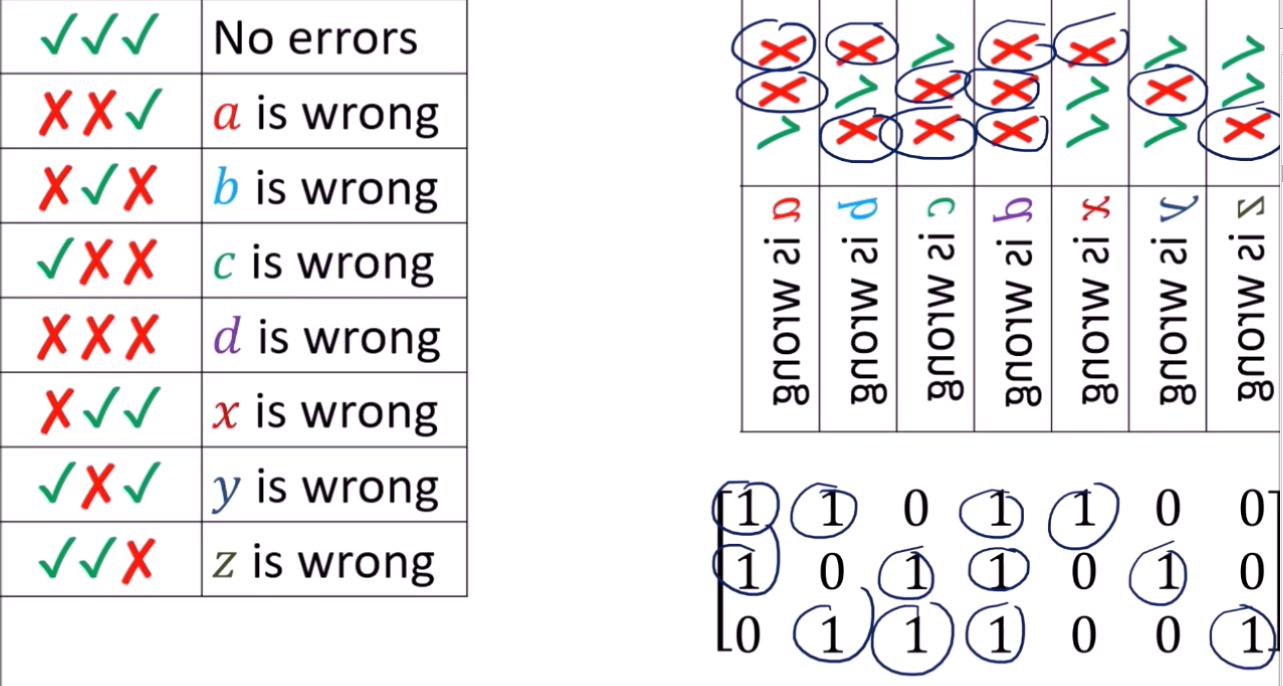

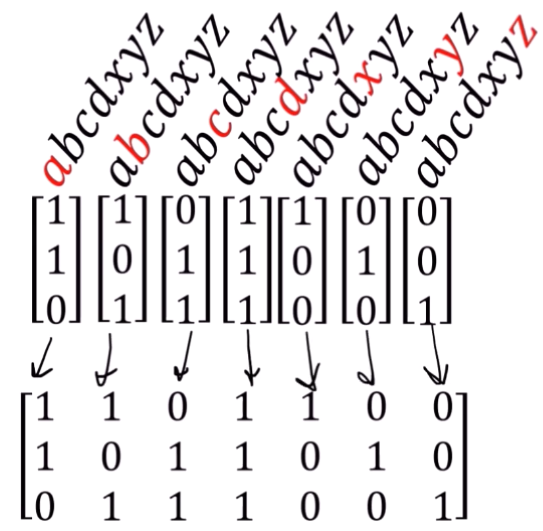

Магическое переворачивание таблицы делает всю работу за нас - нам лишь остается убедиться в коде ниже или на дополнительной картинке, что это все работает. 

Так как такой поворот уникален, то выбор матрицы H - единственный и зависит от G

H = [0 0 0 1 1 1 1;
     0 1 1 0 0 1 1;
     1 0 1 0 1 0 1];

#### Как соотносятся образ одной матрицы с ядром другой матрицы?

*переформулируем: Image(G) = Kernel(H) ?*

*Они **равны** в случае, если в код Хэмминга не внесли ошибку*

Ядро Н  = все вектора V, для которых верно {H*v = 0} , с оговоркой выше под это попадают все вектора кода Хэмминга

    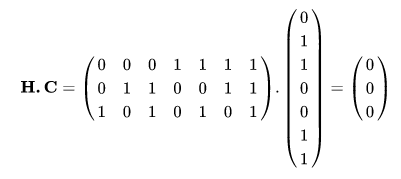

Образ G - это только что переведенные 4 бита в 7 бит кода, тоже по сути все вектора...

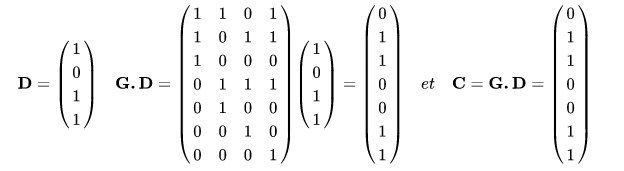

#### **Перевод слова в код с помощью матрицы Хэмминга**

% from 00000 to 11111 - 32 letters in abc
abc = ['А', 'Б', 'В', 'Г', 'Д', 'Е', 'Ё', 'Ж', 'З', 'И', 'Й', 'К', 'Л', 'М', 'Н', 'О', 'П', ...
    'Р', 'С', 'Т', 'У', 'Ф', 'Х', 'Ц', 'Ч', 'Ш', 'Щ', 'Ъ', 'Ы', 'Ь', 'Э', 'Ю'];
word = 'РАКИ';
bin_word = word_to_bin(abc, word)

10001
0
1011
1001


bin_word = '10001000000101101001'

m = length(word)

m = 4


% cell2mat превращает cell array в нормальный тип данных - матрица
divided_word =strread(bin_word,'%4s');

% внутри cell индексы {} , внутри массива/матрицы ()
% word{1}(1)

hamming_msg_vectors = zeros([7,5]);

for i=1:5
    msg_vector = str2num(transpose(divided_word{i}));
    hamming_msg_vectors(:,i) = mod(G*msg_vector,2);
end


### **Вредоносное вмешательство from hackerman**

Термин "умножения" в случае в моем случае не совсем корректно применять, потому что сразу после него мы ищем остаток по модулю 2 от матрицы* <---> ***" * " and  XOR**

#### **Не меняем ничего, расшифровываем**

word0 = hamming_msg_vectors;

for j=1:5
    H_result = mod(H*word0(:,j),2)
end

H_result =      0
     0
     0


H_result =      0
     0
     0


H_result =      0
     0
     0


H_result =      0
     0
     0


H_result =      0
     0
     0



dycrypted_string = hamming_matrix_to_word(word0, abc)

dycrypted_string = 'РАКИ'

Все перемножения = нулевые вектора, то ошибок не было , значит все буквы будут исходными, проверяем...

Так как мы меняем случайный бит, то это не всегда может быть бит информации и поэтому не всегда исходное сообщение нарушится

#### **Меняем 1 бит **

word1 = hamming_msg_vectors;
idx1 = randi([1 7]);
idx2 = randi([1 5]);
word1(idx1, idx2) = not(word1(idx1, idx2));

% Декодируем
hamming_matrix_to_word(word1, abc)

ans = 'РАИИ'

#### Восстанавливаем исходное сообщение

%Пробегаемся по каждой букве, проверяя условие целостности передачи
% Значение вектора result - называется синдромом
problem_letter_index = -999;
problem_letter_bit_index = -999;
health = '0000000';
for j=1:5
    result = mod(H*word1(:,j),2);
    if not(isequal(mod(H*word1(:,j),2),zeros([3,1])))
        result
        % Ищем индексы виновника и инвертируем его
        problem_letter_index = j
        problem_letter_bit_index = bin2dec(transpose(int2str(result)))
        word1(problem_letter_bit_index,problem_letter_index) =  ...
        not(word1(problem_letter_bit_index,problem_letter_index));
    end
end

result =      1
     0
     1


problem_letter_index = 4

problem_letter_bit_index = 5

% Декодируем снова... SUCCESS
hamming_matrix_to_word(word1, abc)

ans = 'РАКИ'

*В остальных случаях, матрица H нам ничем не поможет, поэтому просто давайте полюбуемся на итог*

#### **Меняем 2 бита**

word2 = hamming_msg_vectors;
for i=1:2
    idx1 = randi([1 7]);
    idx2 = randi([1 5]);
    word2(idx1, idx2) = not(word2(idx1, idx2));
end
% Декодируем
hamming_matrix_to_word(word2, abc)

ans = 'РАИИ'

#### **Меняем 3 бита**

word3 = hamming_msg_vectors;
for i=1:3
    idx1 = randi([1 7]);
    idx2 = randi([1 5]);
    word3(idx1, idx2) = not(word3(idx1, idx2));
end
% Декодируем
hamming_matrix_to_word(word3, abc)

ans = 'РАКК'

#### **Меняем 4 бита**

word4 = hamming_msg_vectors;
for i=1:4
    idx1 = randi([1 7]);
    idx2 = randi([1 5]);
    word4(idx1, idx2) = not(word4(idx1, idx2));
end
% Декодируем
hamming_matrix_to_word(word4, abc)

ans = 'РАКБ'

### Вспомогательные функции и их описание

**Перевод слова в двоичное представление**

function result = word_to_bin(abc,word)
    result = '';
    for i=1:length(word)
         index = strfind(abc, word(i))-1;
         disp(dec2bin(index))
         result= append(result,dec2bin(index,5));
    end
    
end


**Перевод матрицы векторов(вектор=1 буква) в слово**

function word = hamming_matrix_to_word(M,abc)
    word = '';
    bytes = '';
    % собираем с кода Хэмминга биты информации в строку
    for i=1:5
        bytes = append(bytes, strcat(int2str(M(3,i)), int2str(M(5,i)), int2str(M(6,i)), int2str(M(7,i))));
    end
    divided_bytes = strread(bytes,'%5s');
    % Теперь эту строку делим по 5 байт, чтобы перевести в символ и делаем
    % из этого слово
    for j=1:4
        word = append(word, abc(bin2dec(divided_bytes{j})+1));
    end

end